#### Repeating the previous Surrogate building sage (Chapter 7) but with addition of the anode consumption related data as an extra input variable to the surrogate model.

Note: The anode consumption related varible is not one of p-value or conductivity related parameter so will be dealt in a different way. 

Also this experiment uses the experimental results from The Parameter_CAxx_CBxx.mlx files (0,5,10,15). So make sure to undertake those experiments in advance which are similar to 2 parameter estimation using surrogate (Chapter 7)

response_data_type = {'voltage', 'normal current density', 'Z_ELECTRIC_FIELD','anode related'};
%response_data_type = {'voltage', 'Z_CURRENT_DENSITY', 'anode related'};
%calibration_data_type = {'voltage'};
%calibration_data_type = {'voltage', 'current density', 'Z_ELECTRIC_FIELD'};

metric = 'nmsq';

IPs_IDs = 32820:32868;

IPs_IDs1 = IPs_IDs(1:2:end);

IDs_current_density = [14390, 7400, 4060, 16000, 19860, 23802, 30002, 23822,21212, 8437];
%IDs_current_density =[27791       27813       27839       27859];
%IDs_current_density = IPs_IDs1;
anode_related_IDs = 1:25:266;

IDs = {py.list(IPs_IDs1), py.list(IDs_current_density),py.list(IPs_IDs1), py.list(anode_related_IDs)};
IDs_mat_arr = {IPs_IDs1, IDs_current_density.', IPs_IDs1,anode_related_IDs.'};

%IDs_types = {'Internal Points','Mesh Points', 'Internal Points','CONSUMPTION_FACTOR','ANODE_CURRENT'};
%IDs_types = {'Internal Points','Mesh Points', 'Internal Points','ANODE_CURRENT'};
IDs_types = {'Internal Points','Mesh Points', 'Internal Points', 'MASS_LOSS_RATE'};
%
%IDs_types = {'Internal Points','Internal Points', 'MASS_LOSS_RATE'};
%py.list(1:2)

parameters_base = {'CA', 'CB'};

The average anode consumption for different year time is something the CP model should predict, but this approach deals it as an Inverse problem.

The average anode consumption rate is added for each of the year during data sampling.

years = [0, 5,10,15];

all_anode_IDs = 1:266;

root_folder1 = 'D:\DOE_nd_data_generation\TIme_step\readyToTimeStepUsingV10_B';

average_cons_factor = average_anode_CONSUMPTION_FACTOR(root_folder1, years, all_anode_IDs);

average_cons_factor

average_cons_factor =          0    0.0754    0.2350    0.4450


anode_IDs = 1:25:255;

res_folder = 'D:\DOE_nd_data_generation\TIme_step\readyToTimeStepUsingV10_B\year_10\Calibration_data';

anode_cons_rate = get_anode_data(res_folder, anode_IDs, 'CONSUMPTION_FACTOR');

%anode_cons_rate

anode_cons_rate =     1.0000    0.2117
  226.0000    0.2365
  101.0000    0.2522
  201.0000    0.2313
   76.0000    0.2707
  176.0000    0.2229
   51.0000    0.2345
  151.0000    0.2417
   26.0000    0.2155
  251.0000    0.2372


%DOE experiment for 2 varaibles using Central Composite Design
Central_composite_points = ccdesign(2, 'type', 'inscribed', 'center' , 1);

DOE_range1 = [0.005, 0.2; 0.005,  0.15];
DOE_range10 = [0.15, 0.35; 0.100,  0.25];
DOE_range15 = [0.15, 0.275; 0.1100,  0.19];

DOE_sample_points= cell(1, length(years)); snapshots_years = DOE_sample_points;

DOE_sample_points{1} = reverse_normalization(Central_composite_points, DOE_range1);
DOE_sample_points{2} = reverse_normalization(Central_composite_points, DOE_range1);
DOE_sample_points{3} = reverse_normalization(Central_composite_points, DOE_range10);
DOE_sample_points{4} = reverse_normalization(Central_composite_points, DOE_range15);

for i = 1:length(years)
    
    source_parameters = {'BARE', 'BARE'};
    
    if years(i) <10
        parameters = strcat(parameters_base, '0', cellstr(string(years(i))));
    else
        parameters = strcat(parameters_base, cellstr(string(years(i))));
    end
    
    parameters_np_array1 = convert_arr_to_python_2d_list(DOE_sample_points{i});
    
    simulation_seed_folder = fullfile(root_folder1,strcat('year_',string(years(i))), 'Initial_files');

    collection_dir = fullfile(root_folder1,strcat('year_',string(years(i))), 'Simulation_results');

    snapshots_py = py.BEASY_IN_OUT2.snapshots_for_given_parameters_and_IDs(py.list(source_parameters), py.list(parameters), parameters_np_array1, py.list(IDs), py.list(response_data_type), simulation_seed_folder, collection_dir, py.list(IDs_types));

    snapshots{i} = double(snapshots_py);
end

DOE_sample_points1_3d = [DOE_sample_points{1}, average_cons_factor(1)*ones(size(DOE_sample_points{1},1),1)];
DOE_sample_points5_3d = [DOE_sample_points{2}, average_cons_factor(2)*ones(size(DOE_sample_points{2},1),1)];
DOE_sample_points10_3d = [DOE_sample_points{3}, average_cons_factor(3)*ones(size(DOE_sample_points{3},1),1)];
DOE_sample_points15_3d = [DOE_sample_points{4}, average_cons_factor(4)*ones(size(DOE_sample_points{4},1),1)];

DOE_sample_points_collected = [DOE_sample_points1_3d(1:2:end,:); DOE_sample_points5_3d(2:2:end,:); 
    DOE_sample_points10_3d(1:2:end,:); DOE_sample_points15_3d(2:2:end,:)];

DOE_sample_points_collected_cells = {DOE_sample_points1_3d(1:2:end,:), 
    DOE_sample_points5_3d(2:2:end,:), DOE_sample_points10_3d(1:2:end,:), DOE_sample_points15_3d(2:2:end,:)};

snapshots_collected = [snapshots{1}(1:2:end,:); snapshots{2}(2:2:end,:);
    snapshots{3}(1:2:end,:); snapshots{4}(2:2:end,:)];

#### Data samples collected at different time-span, now will be used in surrogate-building for the three variables case (PhD Thesis section 8.5.3)

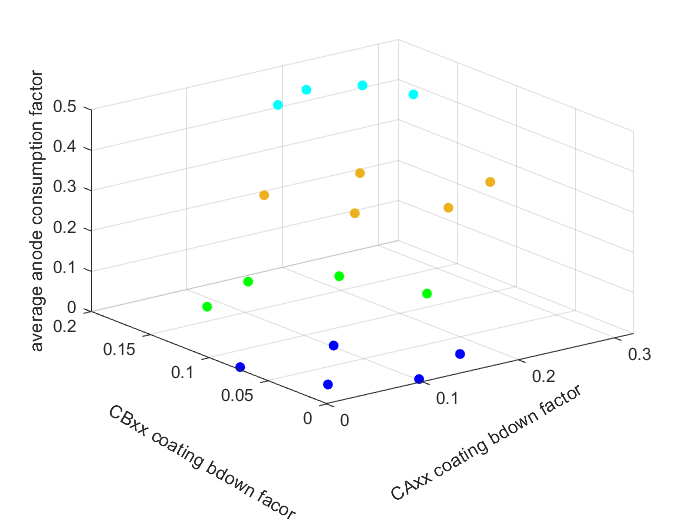

figure;

%scatter3( DOE_sample_points3(:,1),  DOE_sample_points3(:,2),DOE_sample_points3(:,3) ,'filled', 'b');
%scatter3( DOE_sample_points_collected(:,1),  DOE_sample_points_collected(:,2),DOE_sample_points_collected(:,3) ,'filled', 'b');

sampl_idx = 1;
scatter3( DOE_sample_points_collected_cells{sampl_idx}(:,1),  ...
    DOE_sample_points_collected_cells{sampl_idx}(:,2),DOE_sample_points_collected_cells{sampl_idx}(:,3) ,'filled', 'b');
hold on;
sampl_idx = 2;
scatter3( DOE_sample_points_collected_cells{sampl_idx}(:,1),  ...
    DOE_sample_points_collected_cells{sampl_idx}(:,2),DOE_sample_points_collected_cells{sampl_idx}(:,3) ,'filled', 'g');

sampl_idx = 3;
scatter3( DOE_sample_points_collected_cells{sampl_idx}(:,1),  ...
    DOE_sample_points_collected_cells{sampl_idx}(:,2),DOE_sample_points_collected_cells{sampl_idx}(:,3)  ,'filled', 'o');

sampl_idx = 4;
scatter3( DOE_sample_points_collected_cells{sampl_idx}(:,1), ...
    DOE_sample_points_collected_cells{sampl_idx}(:,2),DOE_sample_points_collected_cells{sampl_idx}(:,3)  ,'filled', 'c');


xlabel('CAxx coating bdown factor', 'Rotation', 30);
ylabel('CBxx coating bdown facor', 'Rotation', -30);
zlabel('average anode consumption factor');

%csvwrite('Snapshots_3d.csv', snapshots_collected )
%csvwrite('DOE_sample_points_collected_3d.csv', DOE_sample_points_collected )

%csvwrite('DOE_sample_points_collected_3d.csv', DOE_sample_points_collected )

#### To build the 3 dimensional polynomial fit surrogate, this tool relies upon the MATLAB toolbox *'polyfitn'* .

The toolbox polyfitn need to be downloaded into the system and linked if doesnot exist within the MATLAB.

surrogates_3d = response_surface(DOE_sample_points_collected, snapshots_collected,2);

surrogates_3d

surrogates_3d = 1×71 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1

surrogates_3d{1}

ans = struct with fields:
      ModelTerms: [10×3 double]
    Coefficients: [-629.0825 -202.6927 -13.1925 526.6198 662.3681 -464.8554 23.8937 93.4226 28.4219 -1.0791e+03]
    ParameterVar: [2.9296e+04 1.9555e+05 5.4551e+04 2.7400e+03 4.6670e+05 2.8728e+05 1.1682e+04 1.6283e+04 3.5925e+03 24.7211]
    ParameterStd: [171.1604 442.2061 233.5625 52.3451 683.1581 535.9806 108.0826 127.6067 59.9375 4.9720]
             DoF: 8
               p: [0.0063 0.6589 0.9563 8.1140e-06 0.3607 0.4110 0.8306 0.4850 0.6480 2.2735e-16]
              R2: 0.9959
      AdjustedR2: 0.9912
            RMSE: 1.8967
        VarNames: {'X1'  'X2'  'X3'}


calib_dir = fullfile(root_folder1,'year_20','Calibration_data');
%meas_dir1 = 'C:\Users\msapkota\EXPERIMENT\DOE_nd_data_generation\Model_updated_nonlinear\Parameter_BARE_BBS\Measurement_results3';

files_name = 'BU_TimeStepped_01_20';
%meas_dict = py.BEASY_IN_OUT1.get_output_data_for_IDs_from_simulation_folder(meas_dir, files_name, py.list(calibration_data_type),  py.list(IDs), py.list(IDs_types));

calib_data_IDs = {IPs_IDs1, IDs_current_density};
calib_data_type = response_data_type(1:2);

%meas_data = convert_pydict2data(meas_dict,0);

calib_data_file_err_inc = strcat('data_with_error_',strjoin(response_data_type, '_'), '.xlsx');

%all_position_dict = py.BEASY_IN_OUT2.get_output_data_for_IDs_from_simulation_folder(calib_dir, files_name, py.list(data_type),  py.list(IDs), py.list(IDs_types));


if ~isfile(fullfile(calib_dir, calib_data_file_err_inc))
    all_position_dict = py.BEASY_IN_OUT2.get_output_data_for_IDs_from_simulation_folder(calib_dir, ...
        files_name, py.list(calib_data_type),  py.list({py.list(IPs_IDs), py.list(IDs_current_density)}), py.list(IDs_types));
    all_position_data = convert_pydict2data(all_position_dict,0);
    introduce_error_and_write_file( {IPs_IDs.', IDs_current_density.'},all_position_data, ...
        calib_dir, calib_data_file_err_inc,1);
end

%model_out = output_from_surrogates([2.0, 3.0], surrogates, [17,6]);

calib_data_inc_error = data_from_tables(fullfile(calib_dir, calib_data_file_err_inc), calib_data_IDs,3);

%if we know one of the value we can fix it
figure;

ax = gca;

DOE_range20 = [0.23 0.3; 0.17 0.25; 0.5,0.7];

[plot_data,min_value, min_out_pos20] = plot_objective_with_surrogates(ax, ...

    14    14    74



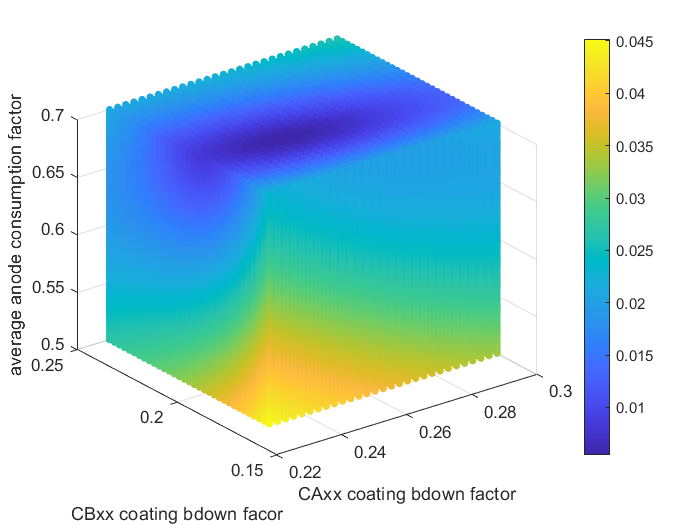

    DOE_range20, surrogates_3d, calib_data_inc_error, 'nmsq', calib_data_type, ...
    cellfun('length',IDs_mat_arr),[1,0.5,0,0], [0.0025,0.0025, 0.0025]);

sol_output_from_surrogate = output_from_surrogates(min_out_pos20, surrogates_3d,cellfun('length', ...
    IDs_mat_arr)); 

xlabel('CAxx coating bdown factor');
ylabel('CBxx coating bdown facor');
zlabel('average anode consumption factor');

min_out_pos20

min_out_pos20 =     0.2625    0.2025    0.6825


%min_out_pos20 = [0.2575    0.2000    0.6925]
testing_par_value = min_out_pos20;

sol_output_from_surrogate = output_from_surrogates(testing_par_value, ...
    surrogates_3d,cellfun('length',IDs_mat_arr)); 

testing_par_value = min_out_pos20(1:2);
root_folder = 'D:\DOE_nd_data_generation\TIme_step\readyToTimeStepUsingV10_B\year_20';
files_name = 'BU_TimeStepped_01_20';

parameters= {'CA20','CB20'};

simulation_seed_folder = fullfile(root_folder, 'Initial_files');

solution_folder = '';
for i = 1:length(parameters)
    solution_folder =   strcat(solution_folder, parameters{i},'_', num2str(testing_par_value(i), ...
        '%.4f'));
    if i~=length(parameters)
        solution_folder = strcat(solution_folder, '_');
    end
end
solution_colection_dir = fullfile(root_folder,'Solution_results');

solution_dir = fullfile(solution_colection_dir, solution_folder);

if ~isfolder(solution_dir)
    solution_dict = py.BEASY_IN_OUT2.get_response_data_for_IDs_and_input_parameters(py.list(source_parameters), ...
        py.list(parameters), testing_par_value, simulation_seed_folder, solution_colection_dir,  py.list(response_data_type), py.list(IDs),  py.list(IDs_types));
    solution_data = convert_pydict2data(solution_dict,1);
else

    solution_dict = py.BEASY_IN_OUT2.get_output_data_for_IDs_from_simulation_folder(solution_dir, ...
        files_name, py.list(response_data_type),  py.list(IDs), py.list(IDs_types));
    solution_data = convert_pydict2data(solution_dict,0);
end

('running_simulation in:', 'D:\\DOE_nd_data_generation\\TIme_step\\readyToTimeStepUsingV10_B\\year_20\\Solution_results\\CA20_0.2625_CB20_0.2025')


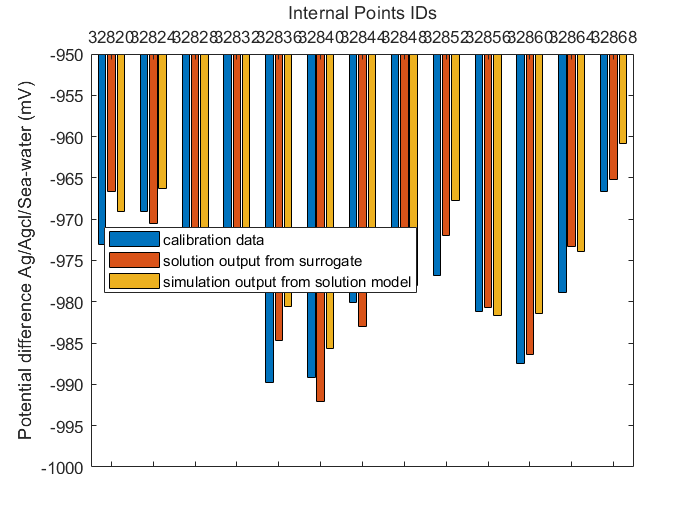

figure;
ax = gca;
%difference_in_bar_chart(ax,simulation_data{1}(1:4:end,:), out_frm_nnet{1}(1:4:end,:),{'simuation predicted data','nnet model predicted data', 'difference'});

%legend_cell = strcat('Data from Simulation on year', strsplit(num2str(time_period)));
legend_cell = {'calibration data', 'solution output from surrogate', 
    'simulation output from solution model'};
data_ID = 1;

response_in_bar_chart(ax, solution_data{data_ID}(1:2:end,:) , ...
    {calib_data_inc_error{data_ID}(1:2:end,:), sol_output_from_surrogate{data_ID}(1:2:end,:), ...
    solution_data{data_ID}(1:2:end,:)}, legend_cell);

xlabel('Internal Points IDs');
%xlabel('Mesh Points IDs');
%xlabel('Data Positional IDs', 'Rotation', 30);
%ylabel('consumption rate (kg/yr)')
%ylabel('Z electric field (micro-V/m)');
%ylabel('Normal current density (mAmp/Sq.m)');
ylim([-1000 -950]);

%ylim([15 22]);
%ylabel('anode Current');
%ylim([1200 2000]);

function average_CONSUMPTION_FACTOR  = average_anode_CONSUMPTION_FACTOR(root_folder_address, years_time, anode_IDs)


average_CONSUMPTION_FACTOR = zeros(1, length(years_time));

for i = 1:length(years_time)
    
    year_t = years_time(i);
    
    response_folder = fullfile(root_folder_address, strcat('year_', string(year_t)), 'Calibration_data');
    
    simulation_files = dir(response_folder);
    files_name = simulation_files(end-3).name;
    files_name = strsplit(files_name, '.');
    files_name = files_name{1};
    
    %anode_file = fullfile(response_folder,strcat(files_name, '.cp_anode_decay'));
    
    initial_anode_data = py.BEASY_IN_OUT2.get_output_data_for_IDs_from_simulation_folder(response_folder, files_name, py.list({'anode related'}),  py.list({py.list(anode_IDs)}), py.list({'CONSUMPTION_FACTOR'}));
     
    initial_anode_data = convert_pydict2data(initial_anode_data,0);
    
    initial_anode_data = initial_anode_data{1};
    
    average_CONSUMPTION_FACTOR(i) = mean(initial_anode_data(:,2));
    
end

end



function anode_data = get_anode_data(response_folder,  anode_IDs, data_type)

    simulation_files = dir(response_folder);
    files_name = simulation_files(end-2).name;
    files_name = strsplit(files_name, '.');
    files_name = files_name{1};
    
    anode_file = fullfile(response_folder,strcat(files_name, '.cp_anode_decay'));
    
    anode_data = py.BEASY_IN_OUT2.get_output_data_for_IDs_from_simulation_folder(response_folder, files_name, py.list({'anode related'}),  py.list({py.list(anode_IDs)}), py.list({data_type}));
     
    
    anode_data = convert_pydict2data(anode_data,0);
    
    anode_data = anode_data{1};
    
end

function de_normaised_data = reverse_normalization(normalised_data, value_ranges)

de_normaised_data = zeros(size(normalised_data));

for i = 1:size(normalised_data, 2)
    
    de_normaised_data(:,i) = value_ranges(i,1)+ diff(value_ranges(i,:))/2 * (normalised_data(:,i)-(-1));
    
end
end